# SVM on (Non-linearly Seperable Data) using polynomial Kernel

## Data Preprocessing

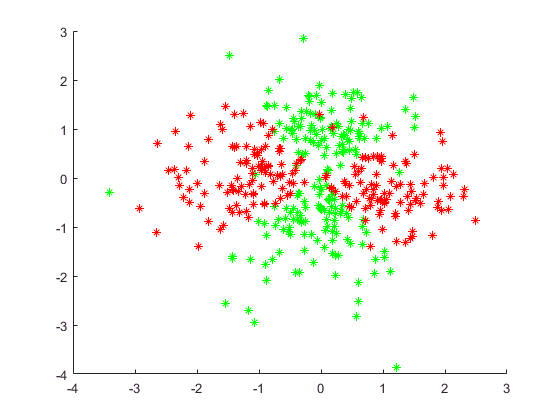

clear all;clc;
a=csvread('conical.csv');
a=[a(:,1:end-1),a(:,end)];

% Divide Data in training and testing sets
[atr,ate] = holdout( a,80);
Xte=ate(:,1:end-1);Yte=ate(:,end);
Xtr=atr(:,1:end-1);Ytr=atr(:,end);
fm_=[];

% Scatter Plot of data
figure
hold on
X=[Xtr;Xte];Y=[Ytr;Yte];
scatter(X(Y==1,1),X(Y==1,2),'*g')
scatter(X(Y==-1,1),X(Y==-1,2),'*r')
hold off

## Applying Polynomial Kernel (Poly2)

% Mapping to higher Dimension
Xtrain=[Xtr(:,1).^2, Xtr(:,2).^2, sqrt(2).*Xtr(:,1).*Xtr(:,2)]; 
Xtest=[Xte(:,1).^2, Xte(:,2).^2, sqrt(2).*Xte(:,1).*Xte(:,2)];
fm_=[];

% for different values of 'C'
for c=[0.2,0.5,0.7,1,2,5] 
    
    % Applying Gradient Ascent
    alpha = grad_asc_poly(Xtrain,Ytr,c,2); 
    
    % Choosing data points for non-zero alphas
    alpha =alpha(alpha>0);Ys=Ytr(alpha>0);Xs=Xtrain(alpha>0,:);   
    
    % Calculating Weights & Bias
    W=sum(alpha.*Ys.*Xs); 
    bias=mean(Ys-(Xs*W'));
    
    % Predictions
    f=sign(Xtest*W'+bias);
    [~,~,fm ] = confusionMatrix(Yte,f);
    fm_=[fm_; c fm];   
    
end

## Optimal 'C' value

[max_fm, indx]=max(fm_(:,2));
c_opt=fm_(indx,1)

c_opt = 0.7000

## Support Vectors

alpha = grad_asc_poly(Xtrain,Ytr,c_opt,2);
alpha =alpha(alpha>0); Ys=Ytr(alpha>0);
Xs=Xtrain(alpha>0,:);

## Weights & Bias

W=sum(alpha.*Ys.*Xs)

W =   -64.8082   79.9812   21.3215


bias=mean(Ys-(Xs*W'))

bias = -1.2331

## Predicted Values

f=sign(Xtest*W'+bias);

## Confusion Matrix

    [~,accuracy,fmeasure ] = confusionMatrix(Yte,f)

accuracy = 0.9750

fmeasure = 0.9706

## Slack Variables

ft=Xtrain*W'+bias;
zeta=max(0,1-Ytr.*ft);
Non_Zero_Zeta=sum(zeta~=0)

Non_Zero_Zeta = 22

...Remark:
% Number of Support Vectors and non-zero $$\zeta$$ should be same

## Plotting the Hyperplane in RKHS

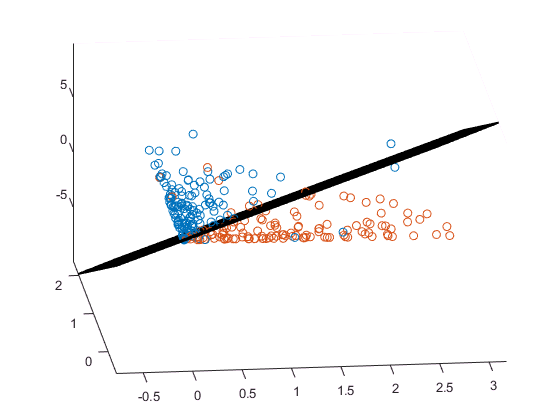

figure
hold on
scatter3(Xtrain(Ytr==1,1),Xtrain(Ytr==1,2),Xtrain(Ytr==1,3))
scatter3(Xtrain(Ytr==-1,1),Xtrain(Ytr==-1,2),Xtrain(Ytr==-1,3))

syms x1 x2
fn=vpa((-bias-W(1)*x1-W(2)*x2)/W(3),4);
fsurf(fn);
fn1=vpa((-1-bias-W(1)*x1-W(2)*x2)/W(3),4);
fsurf(fn1,'r');
fn2=vpa((1-bias-W(1)*x1-W(2)*x2)/W(3),4);
fsurf(fn2,'b');
hold off
xlim([-0.768671802266158 3.18194548168446]);
ylim([-0.585920590295867 2.37704237266709]);
zlim([-9.9233191646289 9.82976725512421]);
view([-6.39999999999989 27.6]);
hold off

## Decision Boundry in Input Space

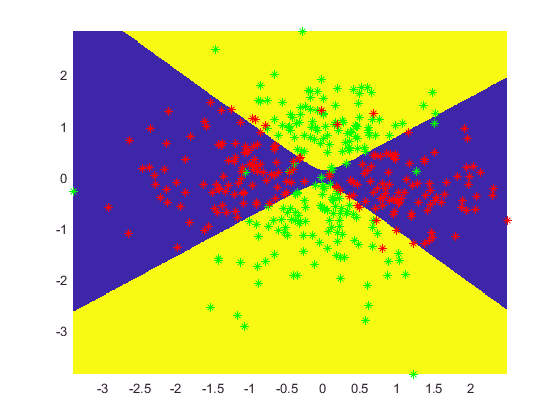

x1range=min(X(:,1)):0.01:max(X(:,1));
x2range=min(X(:,2)):0.01:max(X(:,2));
[x1 x2]=meshgrid(x1range,x2range);
x1p=reshape(x1,1,size(x1,2)*size(x1,1));
x2p=reshape(x2,1,size(x2,2)*size(x2,1));
Xp=[(x1p.^2)' ,(x2p.^2)', (x2p.*x1p)'];
ynp=sign(Xp*W'+bias);
Ynp=reshape(ynp,size(x1));

figure
hold on
imagesc([min(X(:,1)) max(X(:,1))], [min(X(:,2)) max(X(:,2))], Ynp);
scatter(X(Y==1,1),X(Y==1,2),'*g')
scatter(X(Y==-1,1),X(Y==-1,2),'*r')
axis([min(X(:,1)) max(X(:,1)) min(X(:,2)) max(X(:,2))])

hold off

% Bhartendu Thakur,  Machine Learning & Computing